%%% PURPOSE: 
%       Live scripts that use EEGLAB to process the data. Each section
%       requires some user input before hitting 'Run Section'. 
%%% INPUT: 
%       C_trials, the split-up raw data of EEG, EMG, and IMU trials.
%%% OUTPUT: 
%       C_trials_p, processed EEG and EMG trials.

%%% These functions are used to process data with eeglab. See https://eeglab.org/tutorials/11_Scripting/Using_EEGLAB_history.html

%%% Three '%' and ALL-CAPS means manual input is required

## First we must create internal variables, since EEGLAB can't import variables from a struct, and uses a column by row structure. 

eeg_T0=C_trials.eeg_T0(:,1:15)';
eeg_T1=C_trials.eeg_T1(:,1:15)';
eeg_T2=C_trials.eeg_T2(:,1:15)';
eeg_T3=C_trials.eeg_T3(:,1:15)';
eeg_T4=C_trials.eeg_T4(:,1:15)';
emg_T0=C_trials.eeg_T0(:,16)';
emg_T1=C_trials.eeg_T1(:,16)';
emg_T2=C_trials.eeg_T2(:,16)';
emg_T3=C_trials.eeg_T3(:,16)';
emg_T4=C_trials.eeg_T4(:,16)';


# EEG Processing

## Step 1: Starts eeglab, filters data 2-55Hz, plots data.

% Need to run through steps 1-3 for each trial before moving to next trial
% Before clicking 'Run Section', review sections marked by all-caps

%%% UNCOMMENT TRIAL TO WORK ON
% trial = 'eeg_T1';
% trial = 'eeg_T2';
% trial = 'eeg_T3';
 trial = 'eeg_T4';

%opens EEGLab
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Thomas\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 (see >> help eegplugin_VisEd)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)



%%% ENSURE THAT 'channel_locs_1-2_4-12' LOCATION IS CORRECT; USE OTHER FILE FOR PARTICIPANT 3 
EEG = pop_importdata('dataformat','array','nbchan',0,'data',trial,'setname',trial,'srate',500,'pnts',0,'xmin',0,'chanlocs','C:\Users\Thomas\OneDrive - University of Cambridge\USRA\STUDY_DATA\channel_locs_1-2_4-12.ced');

pop_editset(): channel locations file 'C:\Users\Thomas\OneDrive - University of Cambridge\USRA\STUDY_DATA\channel_locs_3.ced' found
readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 15
readlocs() warning: Fewer columns in the input than expected.
                    See >> help readlocs
eeg_checkset warning: number of columns in data (15) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (91001) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


EEG=pop_chanedit(EEG, 'nosedir','+Y');

Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


%Makes dataset 0 with name given above
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

Creating a new ALLEEG dataset 1


pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): [2 55] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [1 56] Hz


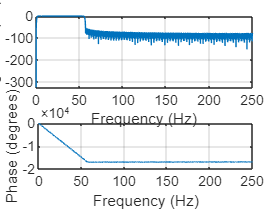

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%2-55Hz filter
EEG = pop_eegfiltnew(EEG, 'locutoff',2,'hicutoff',55,'plotfreqz',1);

%Makes dataset 1 of filtered data
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


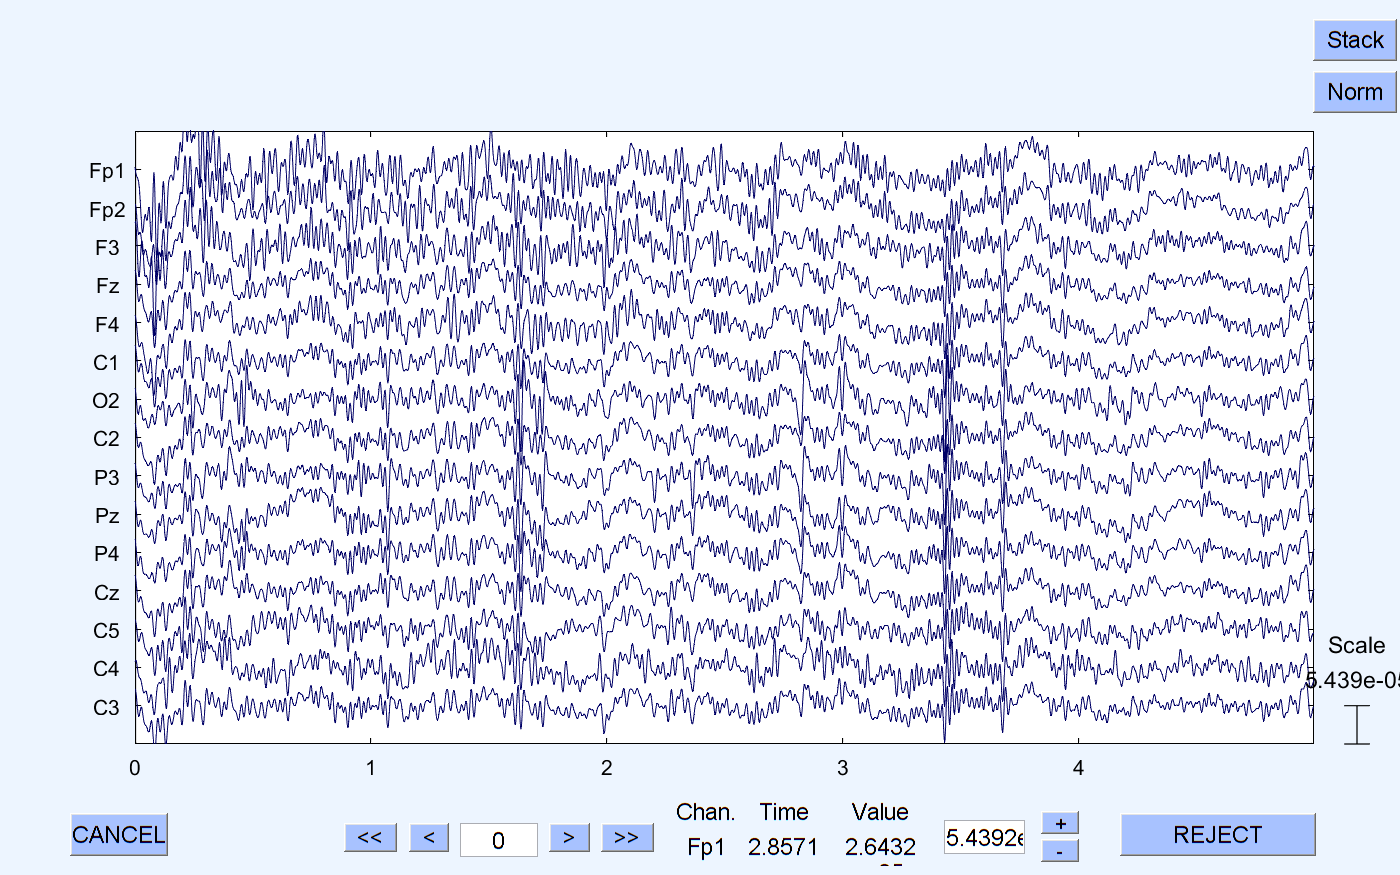

%plots data so you know what to remove
pop_eegplot( EEG, 1, 1, 1);

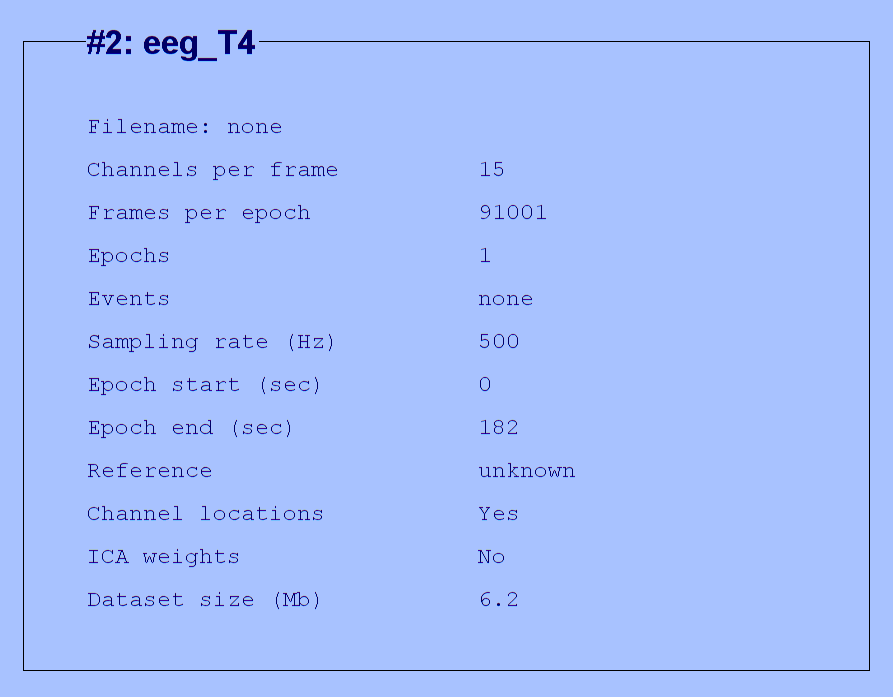

eeglab redraw;

## Step 2: Removes specific channels, re-refs to average, then runs ICA and IC Label

%%% ZOOM OUT ON GRAPH (settings->time range->200); INSERT CHANNEL LABELS TO BE REMOVED FROM THE DATA
% ex. channels_remove = {'Fp1', 'T3'};
channels_remove = {};
% (make note of removed channels on DataProcessing.xlsx)
% This step takes a while

EEG = pop_select( EEG, 'nochannel',channels_remove);
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 2,'setname',strcat(trial,'_filter_chanrem'),'gui','off'); 

Creating a new ALLEEG dataset 3


EEG = eeg_checkset( EEG );
%re-references data
EEG = pop_reref( EEG, []);

Re-referencing data


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 3,'setname',strcat(trial,'_filter_chanrem_reref'),'gui','off'); 

Creating a new ALLEEG dataset 4


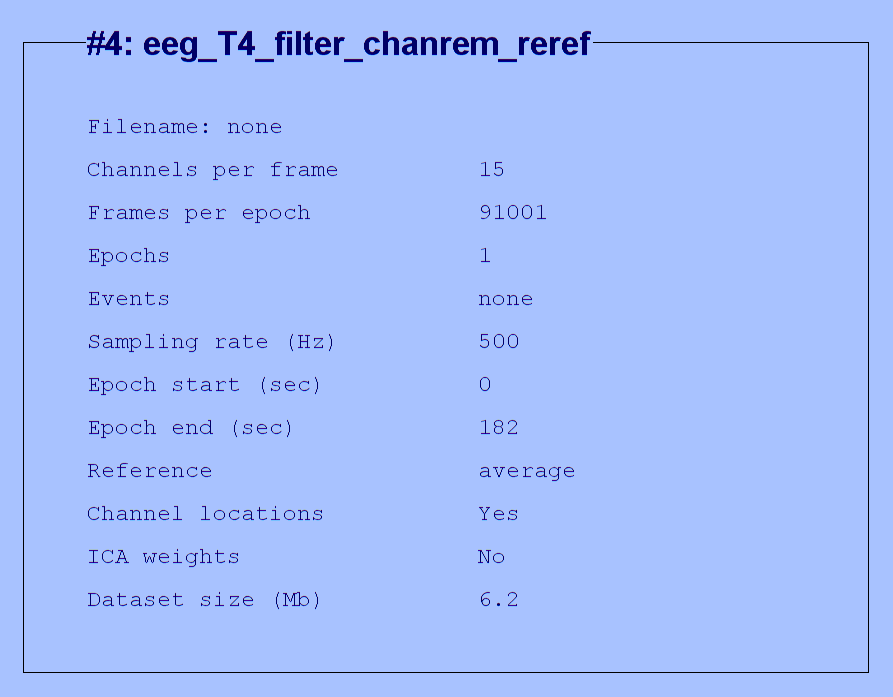

eeglab redraw;

EEG = eeg_checkset( EEG );
EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [15,91001] = 15 channels, 91001 frames/nFinding 15 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 404 frames per ICA weight ((225)^2 = 91001 weights, Initial learning rate will be 0.001, block size 58.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.000138749 to 9.72197e-05
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lrate 0.001000, wcha

[ALLEEG EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);

Scaling components to RMS microvolt


EEG = eeg_checkset( EEG );

Scaling components to RMS microvolt


EEG = pop_iclabel(EEG, 'default');

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


[ALLEEG EEG] = eeg_store(ALLEEG, EEG, CURRENTSET);

Scaling components to RMS microvolt


EEG = eeg_checkset( EEG );

Scaling components to RMS microvolt


## Step 3: Removes specific ICA components, exports to C_trials_p

%%% WITH ICA LABEL (Tools->Classify Comp.->Label Comp.), REMOVE COMPONENTS
%%% WITH <5% CHANGE OF BEING BRAIN AND WALKING COMPONENTS
components_remove = [1  5  8];
% (note removed channels on DataProcessing.xlsx)

EEG = pop_subcomp( EEG, components_remove, 0);

Computing projection and removing 3 components ....


[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 4,'gui','off'); 

Creating a new ALLEEG dataset 5


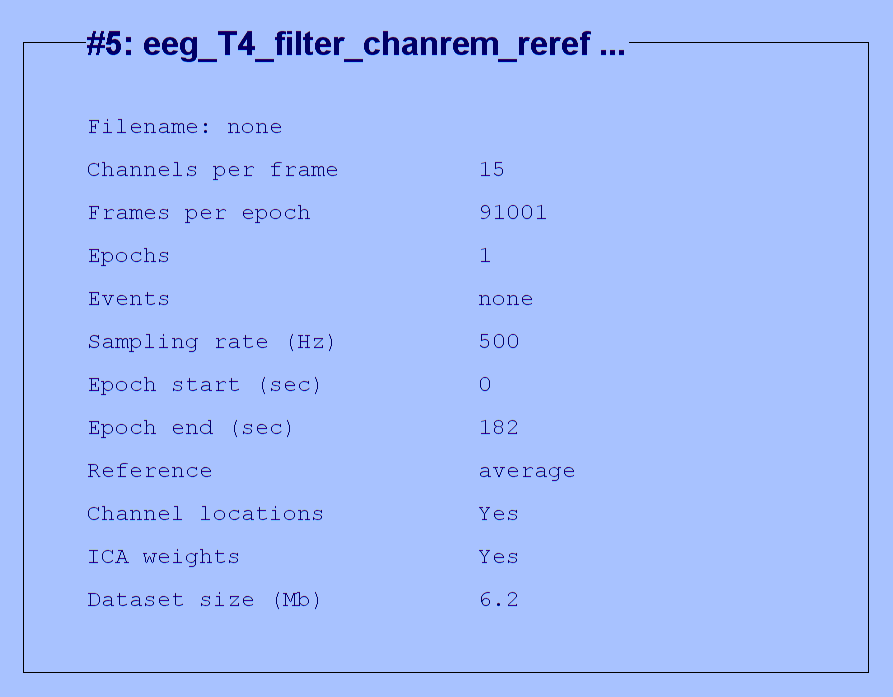

eeglab redraw;


if isequal(trial,'eeg_T1')
    C_trials_p.eeg_T1 = EEG.data';
elseif isequal(trial,'eeg_T2')
    C_trials_p.eeg_T2 = EEG.data';
elseif isequal(trial,'eeg_T3')
    C_trials_p.eeg_T3 = EEG.data';
elseif isequal(trial,'eeg_T4')
    C_trials_p.eeg_T4 = EEG.data';
else
    printf('ERROR');
end

% Repeat steps 1-3 for all trials before continuing

## Later on, the code requires 15 EEG channels. Therefore, insert a column of zeros if a channel was removed in step 2. 

%Unlike Steps 1-3 above, this only needs to be run once at the end. 

zeros_T1=zeros(length(C_trials_p.eeg_T1),1);
zeros_T2=zeros(length(C_trials_p.eeg_T2),1);
zeros_T3=zeros(length(C_trials_p.eeg_T3),1);
zeros_T4=zeros(length(C_trials_p.eeg_T4),1);

%%% CHANGE WHERE ZERO COLS ARE ADDED BASED ON CHANNELS REMOVED FOR EACH TRIAL
C_trials_p.eeg_T1 = [C_trials_p.eeg_T1(:,1:14) zeros_T1];
C_trials_p.eeg_T2 = [C_trials_p.eeg_T2(:,1:14) zeros_T2];
C_trials_p.eeg_T3 = [C_trials_p.eeg_T3(:,1:14) zeros_T3];
C_trials_p.eeg_T4 = [C_trials_p.eeg_T4(:,1:14) zeros_T4];

% For reference, electrode positions for participants 4-12 are:
% Ch1	Fp1
% Ch2	Fp2
% Ch3	F3
% Ch4	Fz
% Ch5	F4
% Ch6	C3
% Ch7	Cz
% Ch8	C4
% Ch9	P3
% Ch10	Pz
% Ch11	P4
% Ch12	Oz
% Ch13	T3
% Ch14	T4
% Ch15	C1

## Deleting a mistakenly added column

% Optional; might be helpful
C_trials_p.eeg_t3(:,4) = [];

# EMG Processing

## High-pass at 2Hz, rectify

% We essentially run the same code section 4 times here. For some reason
% EEGLAB doesn't deal well with running these 4 sections all at once. 

trial = 'emg_T1'

trial = 'emg_T1'

%opens eeglab
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Thomas\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 (see >> help eegplugin_VisEd)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEG = pop_importdata('dataformat','array','nbchan',0,'data',trial,'setname',trial,'srate',500,'pnts',0,'xmin',0);

eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (91001) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


%gives dataset name
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

Creating a new ALLEEG dataset 1


pop_eegfiltnew() - performing 827 point highpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 1 Hz


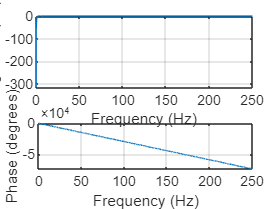

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%high-pass filters at 2 hz
EEG = pop_eegfiltnew(EEG, 'locutoff',2,'plotfreqz',1);

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


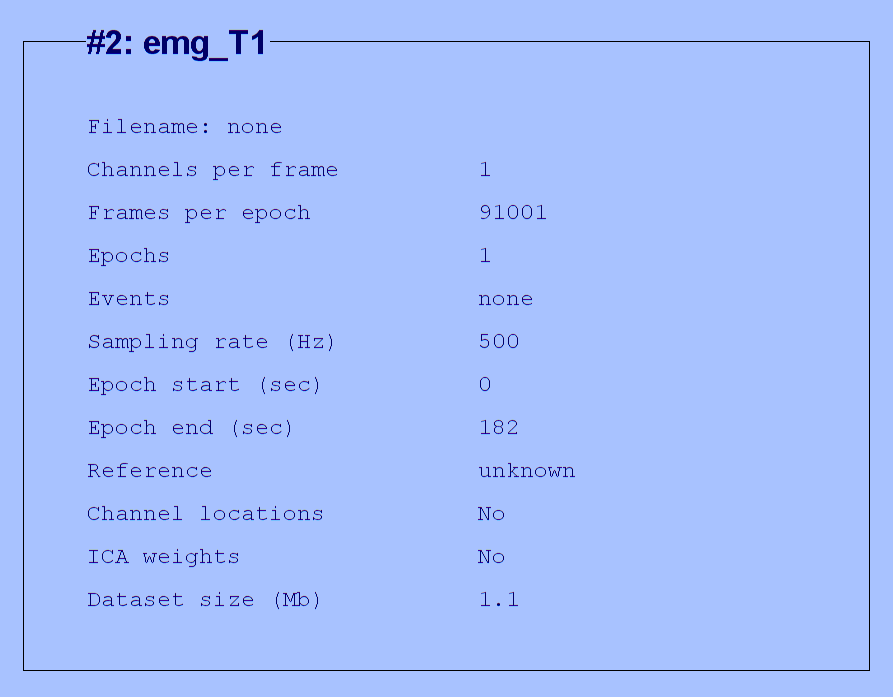

eeglab redraw;

pop_eegplot( EEG, 1, 1, 1);
C_trials_p.emg_T1 = abs(EEG.data');

%%% USE GRAPH TO ENSURE NO EMG DISCONNECTIONS

trial = 'emg_T2'

trial = 'emg_T2'

%opens eeglab
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Thomas\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 (see >> help eegplugin_VisEd)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEG = pop_importdata('dataformat','array','nbchan',0,'data',trial,'setname',trial,'srate',500,'pnts',0,'xmin',0);

eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (91001) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


%gives dataset name
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

Creating a new ALLEEG dataset 1


pop_eegfiltnew() - performing 827 point highpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 1 Hz


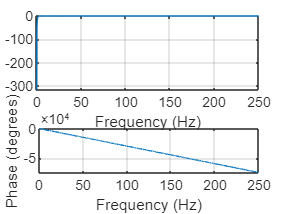

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%high-pass filters at 2 hz
EEG = pop_eegfiltnew(EEG, 'locutoff',2,'plotfreqz',1);

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


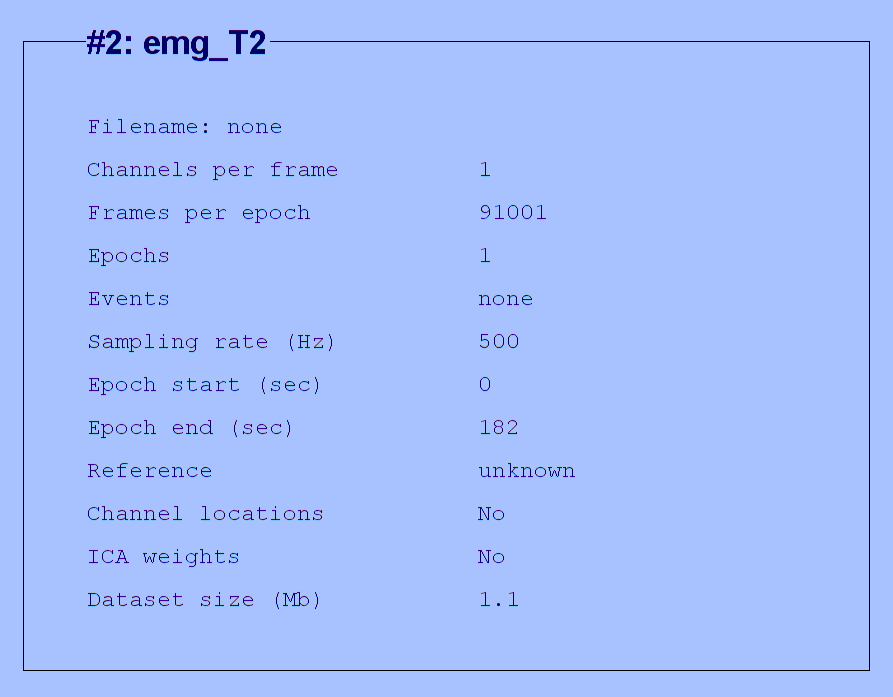

eeglab redraw;

pop_eegplot( EEG, 1, 1, 1);
C_trials_p.emg_T2 = abs(EEG.data');

%%% USE GRAPH TO ENSURE NO EMG DISCONNECTIONS

trial = 'emg_T3'

trial = 'emg_T3'

% %opens eeglab
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Thomas\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 (see >> help eegplugin_VisEd)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEG = pop_importdata('dataformat','array','nbchan',0,'data',trial,'setname',trial,'srate',500,'pnts',0,'xmin',0);

eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (88501) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


%gives dataset name
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

Creating a new ALLEEG dataset 1


pop_eegfiltnew() - performing 827 point highpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 1 Hz


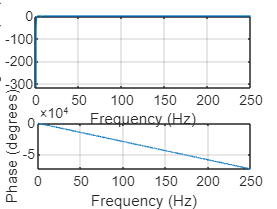

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%high-pass filters at 2 hz
EEG = pop_eegfiltnew(EEG, 'locutoff',2,'plotfreqz',1);

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


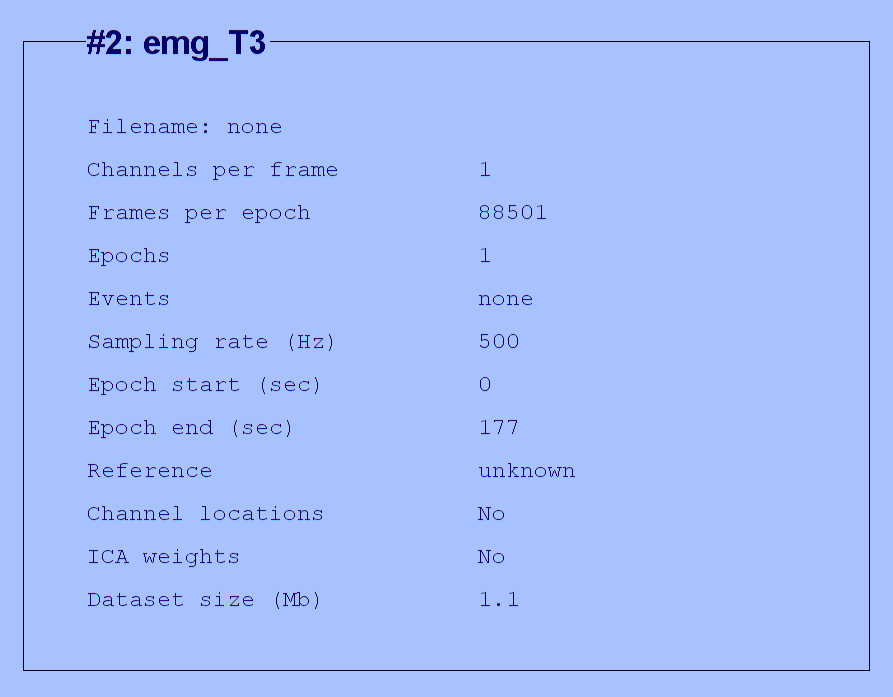

eeglab redraw;

pop_eegplot( EEG, 1, 1, 1);
C_trials_p.emg_T3 = abs(EEG.data');

%%% USE GRAPH TO ENSURE NO EMG DISCONNECTIONS

trial = 'emg_T4'

trial = 'emg_T4'

%opens eeglab
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Thomas\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "VisEd" v1.05 (see >> help eegplugin_VisEd)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata) - new version 2.6 available
EEGLAB: adding "dipfit" v3.7 (see >> help eegplugin_dipfit) - new version 4.3 available
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEG = pop_importdata('dataformat','array','nbchan',0,'data',trial,'setname',trial,'srate',500,'pnts',0,'xmin',0);

eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (91001) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


%gives dataset name
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

Creating a new ALLEEG dataset 1


pop_eegfiltnew() - performing 827 point highpass filtering.
pop_eegfiltnew() - transition band width: 2 Hz
pop_eegfiltnew() - passband edge(s): 2 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 1 Hz


pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


%high-pass filters at 2 hz
EEG = pop_eegfiltnew(EEG, 'locutoff',2,'plotfreqz',1);

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

Creating a new ALLEEG dataset 2


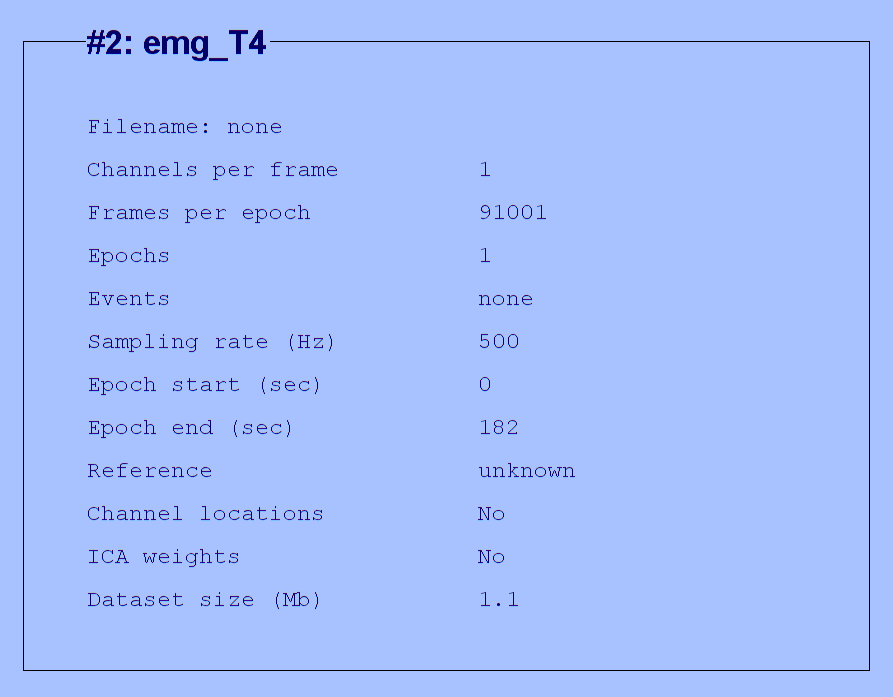

eeglab redraw;

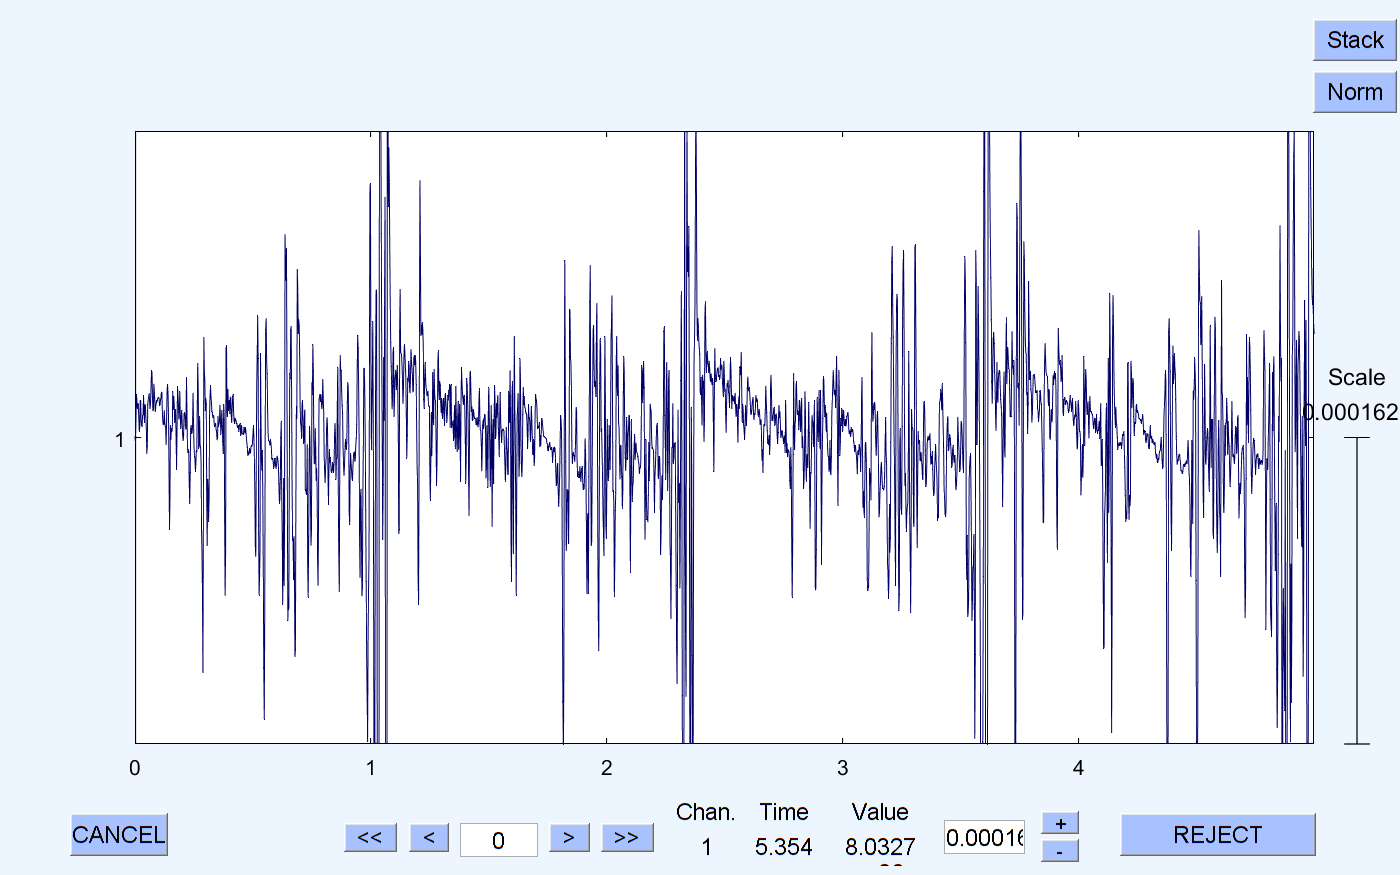

pop_eegplot( EEG, 1, 1, 1);

C_trials_p.emg_T4 = abs(EEG.data');

%%% USE GRAPH TO ENSURE NO EMG DISCONNECTIONS

%Save your workspace as C_trials_p now! Then you don't have to repeat
%these steps when you close Matlab.

%%% INSERT FILE LOCATION (or just 'Save As' workspace)
save('C:\Users\Thomas\OneDrive - University of Cambridge\USRA\STUDY_DATA\Data\XX\C_trials_p.mat')